% P8.4
clear all
syms s
Gc = 2*s + 2;
Gb = 1/((0.2*s + 1)*(s/30 + 1));
G = 1/s;
H = 100/(s^2 + 10*s + 100);
Ts = simplify(Gc*Gb*G/(1 + Gc*Gb*G*H))

$$Ts = \frac{300\,s^{3}+3300\,s^{2}+33000\,s+30000}{s^{5}+45\,s^{4}+600\,s^{3}+5000\,s^{2}+45000\,s+30000}$$

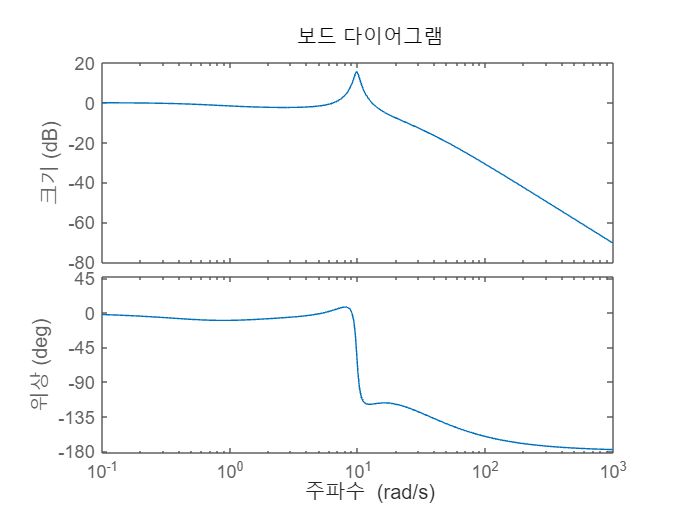


[n, d] = numden(Ts);
num = sym2poly(n);
den = sym2poly(d);
sys = tf(num, den);
bode(sys)